# 5G NR Downlink Channel Estimation

Up to now, we have been assuming the channel is known at the receiver.  In this lab, we will build a simple channel estimator at the UE in a 5G downlink.

In going through the lab, you will learn to:

- Configure and modulate references signals on the DM-RS

- Build a simple channel estimator in frequency and time via kernel regression

- Visualize equalized symbols

- Estimate the noise

- Evaluate the effect of channel estimation error via SNDR and BER

Also, along with this file, you will have to make modifications for these files:

- `NRgNBTxFD.m`:  A class for NR gNB TX frequency-domain simulation

- `NRUERxFD.m`:  A class for NR UE RX frequency-domain simulation

The parts to be modified are labeled `TODO.  `There are three other files that you do not need to modify and do not need to be submitted.

- `FDChan.m`:  A class for frequency-domain channel simulation

- `plotChan.m`:  A function for plotting channels on the OFDM grid

- `kernelReg.m`:  Kernel regression function

Note:  At least on my version of MATLAB, the Live Editor hangs a lot. I have found that you can do the following when this happens.

- Enter something random in the command window like `1+1` .

- The command window will not respond since MATLAB is hung.  But, if you are on the Live Editor tab it will give you a chance to pause the process.

- Hit the pause and then MATLAB will stop where it is stuck.  Sometimes there is an error in your code, and sometimes MATLAB just decides to hang for no reason.

- A this point, you can Quit Debugging and get back control.

**Submission**:  Complete this MATLAB live file and the TODO sections in `NRgNBTxFD.m `and  `NRUERxFD.m`.  Run the code.  Print this file and `NRgNBTxFD.m `and  `NRUERxFD.m`  to PDF.  Merge to a single PDF and submit the PDF for grading.

## Configuring the System Parameters

In this lab, we will configure the parameters with the following parameters that corresponds to a 10 MHz carrier.

fc = 2.3e9;                % Carrier frequency
SubcarrierSpacing = 15;    % SCS in kHZ
NRB = 51;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB
tot_nsc = NRB*nscPerRB; % total number of sub-carriers

Similar to the previous lab, get the `carrierConfig` and `waveformConfig` with the `nrCarrierConfig` and `nrOFDMInfo` methods in the 5G Toolbox.

carrierConfig = nrCarrierConfig('NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

## Configuring the DM-RS and PDSCH

The 5G NR DM-RS is highly configurable.  Set the parameters in the following function to configure the DM-RS: 3 REs per symbol at 2 different symbols in time (a total of 6 REs per RB).  

% TODO:  Set the DM-RS config
  dmrsConfig = nrPDSCHDMRSConfig(...
      'NumCDMGroupsWithoutData', 1, ...  % No unused DM-RS
      'DMRSAdditionalPosition', 1, ...   % Set this correctly
      'DMRSConfigurationType', 2);      % Set this correctly

Given the DM-RS configuration, we set the PDSCH:

% Configure the physical downlink shared channel parameters
pdschConfig = nrPDSCHConfig();
pdschConfig.NSizeBWP = [];   % Empty implies that the value is equal to NSizeGrid
pdschConfig.NStartBWP = [];  % Empty implies that the value is equal to NStartGrid
pdschConfig.PRBSet = (0:NRB-1);   % Allocate the complete carrier
pdschConfig.SymbolAllocation = [0 14]; % Symbol allocation [S L]
pdschConfig.MappingType = 'A'; % PDSCH mapping type ('A' or 'B')
pdschConfig.EnablePTRS = true;
pdschConfig.PTRS =  nrPDSCHPTRSConfig();
pdschConfig.DMRS = dmrsConfig;

## Creating the gNB Transmitter

Complete the code for the transmitter in the file `NRgNBTxFD.m` .  The code will:

- Generate random bits for the PDSCH

- Modulate the bits to the PDSCH symbols

- Determine the PT-RS and DM-RS symbols and add them to the TX grid

% TODO:  Finish the code in the NRgNBTxFD.m class

Once you have completed the code you can create a TX object.

tx = NRgNBTxFD(carrierConfig, pdschConfig);
tx.step();

Use the following command to plot the channels.

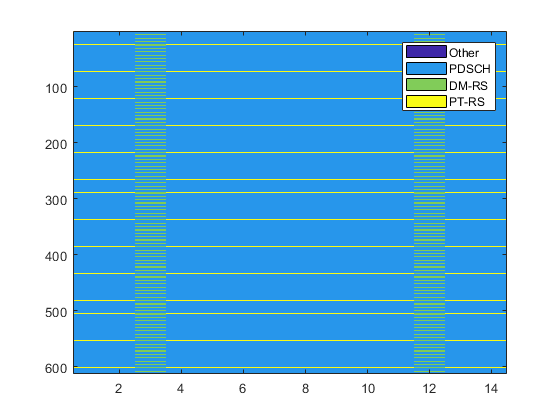

plotChan(tx.txGridChan, tx.chanNames);

Now plot the channel types for one RB. 

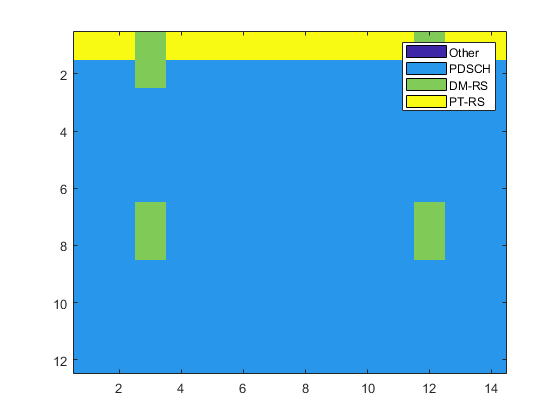

% TODO
plotChan(tx.txGridChan(1:12,:), tx.chanNames);

Compute and print the fraction of REs used for each channel.

% TODO (partially taken from the demo code)
chanNames = tx.chanNames;
for i = 1:length(chanNames)
    p = mean(tx.txGridChan==i-1, 'all');
    fprintf('Channel %-7s:  %7.3f\n', chanNames{i}, p);
end

Channel Other  :    0.000
Channel PDSCH  :    0.916
Channel DM-RS  :    0.048
Channel PT-RS  :    0.036


## Simulating the Frequency-Domain OFDM Channel

A helper funciton at the end of the script creates random channel parameters that we will use repeatedly.

% Channel parameters
dlymean = 200e-9;  % Mean delay spread
aoaAzSpread = 60;  % AoA azimuth spread
aoaElSpread = 20;  % AoA azimuth spread

% Get channel parameters
[gain, dly, aoaAz, aoaEl] = randParam(dlymean, aoaAzSpread, aoaElSpread);

Given the channel parameters, we also set RX velocity.  You can try faster motion as well.

% Mobile velocity vector in m/s
rxVel = [25,0,0]';

Then we construct the channel

% Parameters for computing the SNR
Etx = 1;        % Average transmitted symbol energy
snrAvg = 20;   % Average SNR

% Create a FD channel
fdchan = FDChan(carrierConfig, 'gain', gain, 'dly', dly, 'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
    'rxVel', rxVel, 'Etx', Etx, 'EsN0Avg', snrAvg, 'fc', fc);

The frequency-domain channel has the identical syntax as the the previous lab as well as the demo.  

To illusrate the channel, we first create a grid of TX symbols.  For now, we will just set them all to ones.

NumLayers = 1;
txGrid = nrResourceGrid(carrierConfig, NumLayers);
txGrid(:) = 1;

Set the `frameNum=0 and slotNum=0 `and call the `fdchan.step()` method to get the channel grid and noise variance.  Compute a channel SNR matrix, `chanSnr(i,j) `representing the SNR in dB per RE.  Plot `chanSnr` with the `imagesc` command.  You should see some frequency selective fading.  But, minimal fast fading.  Nevertheless, there is sufficient variation over time that you would not want to assume the channel is constant over the slot.

frameNum = 0;
slotNum = 0;

% TODO:
[~, chanGrid, ~] = fdchan.step(txGrid, frameNum, slotNum);

Plot the real  components of the channel at symbol = 8;

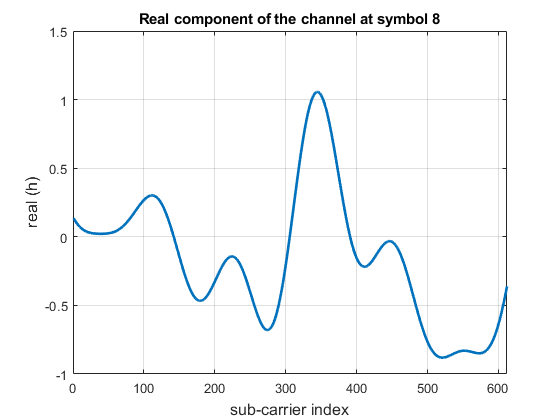

isym = 8;

% TODO:  
h = chanGrid(:,isym);
figure;
plot(real(h), 'LineWidth', 2);
grid on;
xlabel('sub-carrier index', 'FontSize', 12);
xlim([0 tot_nsc]);
ylabel('real (h)', 'FontSize',12);
title("Real component of the channel at symbol 8");

## Building the a Channel Estimator

Now complete the `chanEst` method in the RX class, `NRUERxFD.m`.  Tthe channel estimator function:

- Extracts the DM-RS symbols

- Finds the sub-carrier indices for each symbol on which there are DM-RS references

- Creates the raw channel estimates on each such symbol

- Interpolates over time to get the final estimate over the entire 

% TODO:  Complete the code in the chanEst method in the NRUERxFD class

Once you are done with this you can test the channel estimate

% Create TX and RX
tx = NRgNBTxFD(carrierConfig, pdschConfig);
rx = NRUERxFD(carrierConfig, pdschConfig);

% Create a FD channel
snr = 20;
[gain, dly, aoaAz, aoaEl] = randParam(dlymean, aoaAzSpread, aoaElSpread);
fdchan = FDChan(carrierConfig, 'gain', gain, 'dly', dly, 'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
    'rxVel', rxVel, 'Etx', Etx, 'EsN0Avg', snr, 'fc', fc);
        
% Run the TX
txGrid = tx.step();

% Run the channel
frameNum = 0;
slotNum = 0;
[rxGrid, chanGrid, ~] = fdchan.step(txGrid, frameNum, slotNum);

% Run the channel estimator
rx.chanEst(rxGrid);
chanEstGrid = rx.chanEstGrid;

isym = 12;
h = chanGrid(:,isym);
hest = chanEstGrid(:,isym); 
% chanEstDmrs = rx.chanEstDmr;
% hest = chanEstDmrs(:,2); % estimated channel thorugh DMRS at symbol 12
figure;
plot(real(h), 'LineWidth', 2); hold on;
plot(real(hest), 'LineWidth', 2); hold off;
legend("True", "Estimated");
grid on;
xlabel('sub-carrier index', 'FontSize', 12);
xlim([0 tot_nsc]);
ylabel('real (h)', 'FontSize',12);
title("Real component of the channel at symbol 12");

% noiseEst = rx.noiseEst;

For each i, plot the weightings over time, `rx.Wtime(i,j) vs. j.  `This indicates the weighting of the OFDM symbols on different reference symbols.  

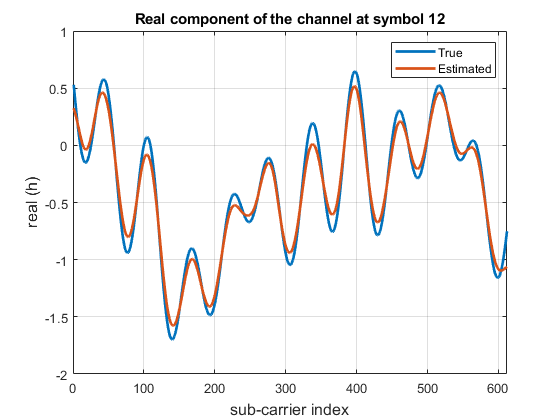

% TODO
Wtime = rx.Wtime;
figure;

[i_v, j_v] = size(Wtime);
for i=1:i_v
    plot(1:j_v, Wtime(i,:), "Linewidth",2); hold on;
end
hold off; grid on;
legend("RS 3", "RS 12", "location", "north");
xlim([1 j_v]);
ylabel("Weighting"); xlabel("Time symbols");
title("Weighting for each reference symbol");

Get the channel estimate save in `rx.chanEstGrid` and plot the true and estiamted real values of the channel for the symbols 7 and 12.  Use subplots.   Since we ran the channel estimation at 20 dB, the channel estimation should look quite close on both symbols.  

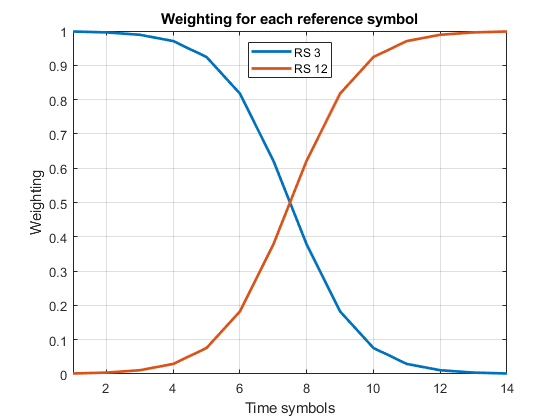

isymPlot = [7,12];
chanEstGrid = rx.chanEstGrid;
% TODO
figure;


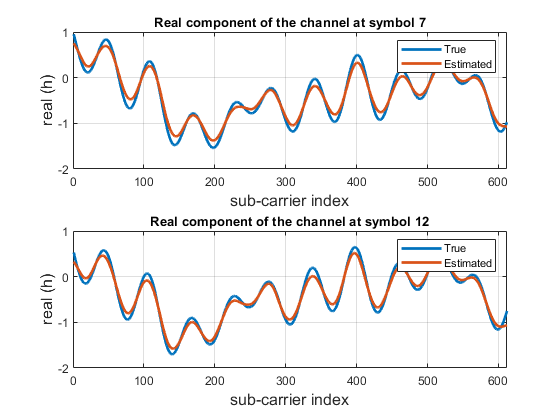

for i=1:length(isymPlot)
    subplot(2,1,i);
    isym = isymPlot(i);
    h = chanGrid(:,isym);
    hest = chanEstGrid(:,isym);
    plot(real(h), 'LineWidth', 2); hold on;
    plot(real(hest), 'LineWidth', 2); hold off;
    legend("True", "Estimated");
    grid on;
    xlabel('sub-carrier index', 'FontSize', 12);
    xlim([0 tot_nsc]);
    ylabel('real (h)', 'FontSize',12);
    title("Real component of the channel at symbol "+num2str(isym));    
end

Compute and print the MSE of the channel estimate by comapring `rx.chanEstGrid` to `chanGrid`.

% TODO:
mse =  mean(abs(chanEstGrid-chanGrid).^2, "all");
fprintf(1, 'The MSE of the channel estimate is = %f\n', mse);

The MSE of the channel estimate is = 0.021941


fprintf(1, 'The MSE of the channel estimate [dB] is = %f\n', 10*log10(mse));

The MSE of the channel estimate [dB] is = -16.587506


## Using the Channel Estimation for Equalization and Demodulation

Complete the `stepImpl` method in `NRUERxFD` class which performs the equalization and hard decision decoding of the bits.  Note that if we were building the full receiver, we would compute the LLRs and then send these to the decoder as we did in the previous lab.

% TODO:  Complete the TODO sections in stepImpl method of NRUERxFD.m

Once you have done this you can complete the following code to test the receiver.  We will compute the BER using the true channel and the estimated channel and print the results. They should be similar.

% Create TX and RX
tx = NRgNBTxFD(carrierConfig, pdschConfig);
rx = NRUERxFD(carrierConfig, pdschConfig);

% Create a FD channel
snr = 20;
[gain, dly, aoaAz, aoaEl] = randParam(dlymean, aoaAzSpread, aoaElSpread);
fdchan = FDChan(carrierConfig, 'gain', gain, 'dly', dly, 'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
                'rxVel', rxVel, 'Etx', Etx, 'EsN0Avg', snr, 'fc', fc);
        
% Run the TX
txGrid = tx.step();

% Run the channel
frameNum = 0;
slotNum = 0;
[rxGrid, chanGrid, noiseVar] = fdchan.step(txGrid, frameNum, slotNum);

% Run the RX with the estimated channel
rx.chanEst(rxGrid); % estimate the channel
rxBits = rx.step(rxGrid);

% TODO:  Compare the rxBits to tx.txBits to compute the BER with channel
% estimation error
berChanEst = mean(tx.txBits ~= rxBits);

% TODO:  Run the RX where we supply the true channel and noise
rxBits_t = rx.step(rxGrid, chanGrid, noiseVar);
berChanTrue = mean(tx.txBits ~= rxBits_t);

% Print results
fprintf('BER chan est  = %12.4e\n', berChanEst);
fprintf('BER chan true = %12.4e\n', berChanTrue);    

## Testing over an SNR Range

We conclude by testing over a range of SNRs.  At each SNR, we run a number of slots and measure the BER with the true and estimated channel.  We also estimate the SNDR.

% SNR values to test
snrTest = (0:2:40)';

BER chan est  =   1.2933e-02


nsnr = length(snrTest);

BER chan true =   9.3017e-03



% number of trials at each SNR
ntrial = 50;

% Create TX and RX
tx = NRgNBTxFD(carrierConfig, pdschConfig);
rx = NRUERxFD(carrierConfig, pdschConfig);

% Create arrays to store results
nmeth = 2;  % 1=BER with estimated chan, 2=BER with true chan
ber = zeros(ntrial, nsnr, nmeth);
berAvg = zeros(nsnr, nmeth);
sndr = zeros(nsnr, 1);

for isnr = 1:nsnr
    snr = snrTest(isnr);
    
    % Distortion and signal energy in each trial
    distEnergy = zeros(ntrial,1);
    sigEnergy = zeros(ntrial,1);
    
    for itrial = 1:ntrial
        
        % Create a FD channel
        [gain, dly, aoaAz, aoaEl] = randParam(dlymean, aoaAzSpread, aoaElSpread);
        fdchan = FDChan(carrierConfig, 'gain', gain, 'dly', dly, 'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
            'rxVel', rxVel, 'Etx', Etx, 'EsN0Avg', snr, 'fc', fc);
                
        % TODO:  Run the TX
        txGrid = tx.step();
        
        
        % TODO:  Run the channel with frameNum = 0 and slotNum = 0
        [rxGrid, chanGrid, noiseVar] = fdchan.step(txGrid, 0, 0);
        
        
        % TODO:  Run the RX with the channel estimate
        rx.chanEst(rxGrid);
        rxBits = rx.step(rxGrid);
        
        % TODO:  Get the BER with the channel estimate
        ber(itrial, isnr, 1) = mean(tx.txBits ~= rxBits);
        
        % TODO:  Measure distortion and signal energy using the PDSCH
        % symbols and channel in rx.pdschSym and rx.pdschChan at the RX and
        % tx.pdschSym at the TX
        distEnergy(itrial) = mean(abs(rx.pdschSym - rx.pdschChan.*tx.pdschSym).^2);
        sigEnergy(itrial) = mean(abs(rx.pdschChan.*tx.pdschSym).^2);
        
        % TODO:  Run the RX with the true channel and noise variance
        rxBits = rx.step(rxGrid, chanGrid, noiseVar);
        
        % TODO:  Get the BER
        ber(itrial, isnr, 2) = mean(tx.txBits ~= rxBits);
                               
    end
    
    % TODO:  Measure the average BER for the SNR
    berAvg(isnr,:) = squeeze(mean(ber(:,isnr,:),1));  %squeeze(mean(ber, 1));
    
    % TODO:  Measure the SNDR
    sndr(isnr) = pow2db(mean(sigEnergy)/mean(distEnergy));
    
    % Plot the progress
    fprintf('SNR=%7.2f SNDR=%7.2f BER = %12.4e %12.4e\n', snr, sndr(isnr), berAvg(isnr,:));
end

SNR=   0.00 SNDR=  -0.64 BER =   2.3839e-01   2.1783e-01
SNR=   2.00 SNDR=   1.67 BER =   1.7504e-01   1.5859e-01
SNR=   4.00 SNDR=   3.31 BER =   1.4186e-01   1.2808e-01
SNR=   6.00 SNDR=   5.38 BER =   9.6346e-02   8.5623e-02
SNR=   8.00 SNDR=   7.26 BER =   7.1620e-02   6.2912e-02
SNR=  10.00 SNDR=   8.58 BER =   5.5622e-02   4.8807e-02
SNR=  12.00 SNDR=  10.87 BER =   3.2508e-02   2.7722e-02
SNR=  14.00 SNDR=  12.23 BER =   2.1086e-02   1.7960e-02
SNR=  16.00 SNDR=  14.00 BER =   1.3828e-02   1.1397e-02
SNR=  18.00 SNDR=  15.57 BER =   1.0313e-02   7.9880e-03
SNR=  20.00 SNDR=  16.29 BER =   6.6055e-03   5.3759e-03
SNR=  22.00 SNDR=  17.53 BER =   5.3568e-03   3.5474e-03
SNR=  24.00 SNDR=  18.10 BER =   3.5805e-03   2.3751e-03
SNR=  26.00 SNDR=  18.81 BER =   2.1547e-03   1.5405e-03
SNR=  28.00 SNDR=  19.19 BER =   1.7801e-03   9.2380e-04
SNR=  30.00 SNDR=  19.31 BER =   1.2959e-03   4.8675e-04
SNR=  32.00 SNDR=  19.35 BER =   8.2187e-04   2.4083e-04
SNR=  34.00 SNDR=  19.70 BER = 

Plot the BER with the true and estimated channels.

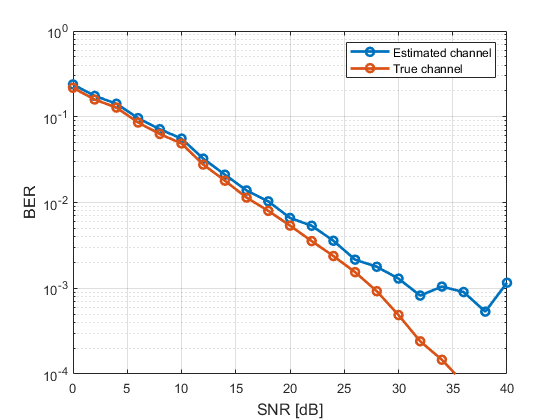

% TODO.
figure;
semilogy(snrTest, berAvg, "o-", "LineWidth", 2);
grid on;
xlabel("SNR [dB]", "Fontsize", 12);
ylabel("BER", "Fontsize", 12);
ylim([1e-4,1]);
legend("Estimated channel", "True channel");

Plot the SNDR vs. SNR. You should see it saturate arond 20 dB of performance since there is mobility across the channel.

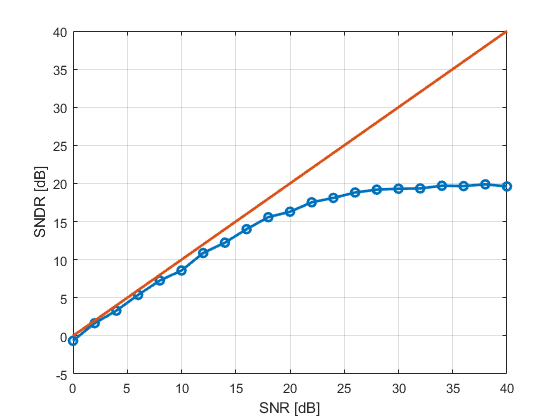

% TODO
figure;
plot(snrTest, sndr, 'o-', 'LineWidth', 2);
hold on;
plot(snrTest, snrTest, '-', 'LineWidth', 2);
hold off;
grid on;
xlabel('SNR [dB]');
ylabel('SNDR [dB]');

I incremented the number of snrs to test (up to 40 dB) in order to better observe saturation around 20 dB.

function [gain, dly, aoaAz, aoaEl] = randParam(dlymean, aoaAzSpread, aoaElSpread)
    % Generates random parameters for a cluster of paths with
    % angular and delay spread
    
    % Default values
    if nargin < 1
        dlymean = 200e-9;
    end
    if nargin < 2
        aoaAzSpread = 60;
        aoaElSpread = 20;
    end
    
    % Create sub-path parameters
    npaths = 20;
    gain = zeros(npaths,1);      % path gain in dB
    dly = exprnd(dlymean, npaths,1);  % path delays in seconds
    aoaAz = unifrnd(-aoaAzSpread, aoaAzSpread, npaths,1);  % angles of arrival
    aoaEl = unifrnd(-aoaElSpread, aoaElSpread,npaths,1);
end
